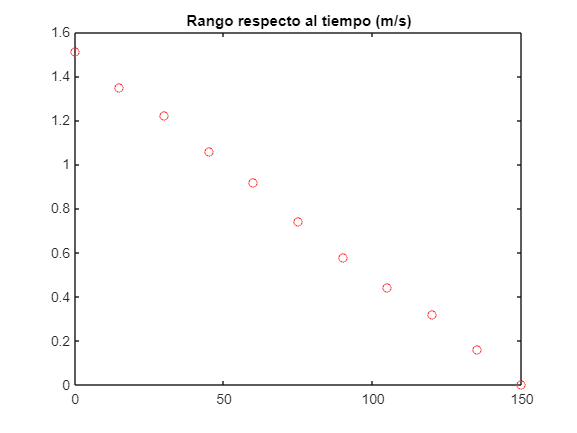

%rango con datos experimentales
rango = [1.51;1.35;1.22;1.06;0.92;0.74;0.58;0.44;0.32;0.16;0];
tiempo = 0:15:150;

plot(tiempo, rango, 'ro')
title('Rango respecto al tiempo (m/s)');

%ajuste de curvas para conocer pendiente (velocidad)
x = tiempo;
x_columna = x';
y = rango;
y_columna = y;

X = [x_columna,ones(numel (x),1)]

X =      0     1
    15     1
    30     1
    45     1
    60     1
    75     1
    90     1
   105     1
   120     1
   135     1


I = X\y_columna

I =    -0.0101
    1.5086


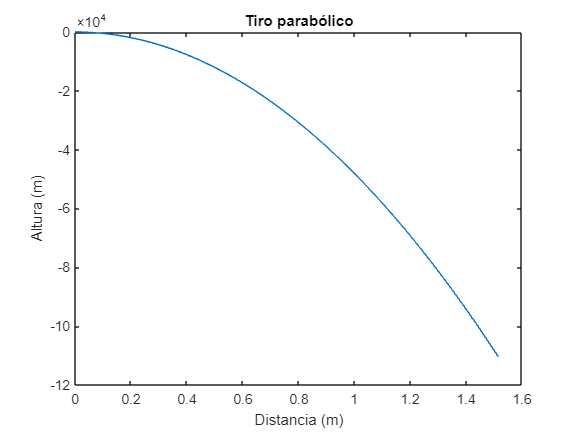

%Tiro Parabólico
g = 9.81; 
v0 = 0.0101; 
angulo = 0; 
t_final = 150;

t = linspace(0, t_final, 100); % Vector de tiempo
x = v0 * cosd(angulo) * t; 
y = v0 * sind(angulo) * t - 0.5 * g * t.^2;

plot(x, y);
title('Tiro parabólico');
xlabel('Distancia (m)');
ylabel('Altura (m)');

%volumen
Vmax = 3.2436e-3;
Ah = 1.4522e-5;
g = 9.81;
At = 4.1853e-3;
t = 0:15:115;
V= (((Ah * sqrt(2 * g)) / sqrt(At)) .* t -  0.1139) / 2;
V_tiempo=V.^2

V_tiempo =     0.0032    0.0024    0.0018    0.0012    0.0007    0.0004    0.0001    0.0000


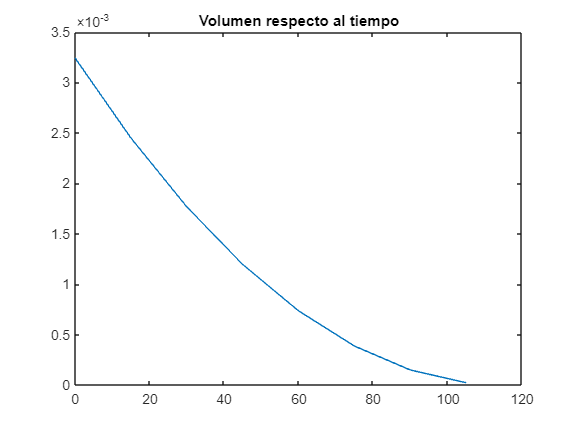

plot(t,V_tiempo)
title('Volumen respecto al tiempo');

V_campo = -0.001:0.0005:0.004;
[t,V] = meshgrid(t,V_campo);
m = 2.1428;
vx = 1./sqrt(1 + m.^2);
vy = m./sqrt(1 + m.^2);
%quiver(t,V,vx,vy)

Intentamos la misma implementación que vimos en clase pero por alguna razón el tamaño de t no coincide con el de vx. Por alguna razón en el ejemplo que vimos en clase, el equivalente a V no tiene dimensiones, muy extraño. Cualquier intento hasta con otras funciones no nos generó el campo de pendientes de manera correcta. La pendiente en este caso se calculó con la fórmula general de la pendiente (y2-y1 / x2-x1). A diferencia del ejemplo visto en clase, no encontramos una pendiente para nuestra ecuación. Estrictamente hablando sabemos que la pendiente sería el caudal, denotado por A*v. Pero la ecuación diferencial completa original es una extensión de esa pendiente, así que no nos hizo mucho sentido. Intentamos haciendo un ajuste de curvas como lo vimos en clase, sacando un valor preciso para la velocidad, y así calcular el caudal, pero no funcionó tampoco. Queremos que esto sea testimonio de que entendimos los conceptos de clase e intentamos de todo, pero no obtuvimos el resultado esperado :(

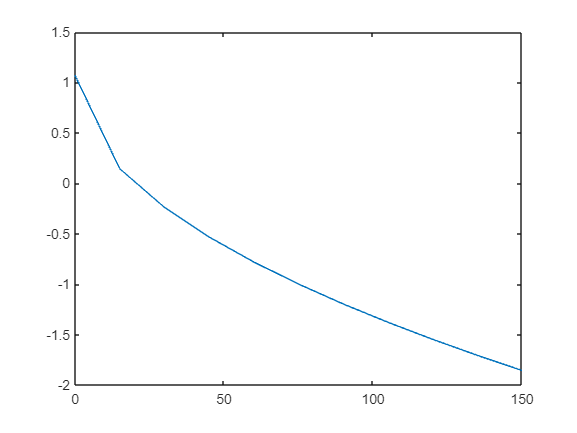

%altura
d = 997;
velocidad = 0.01;
c = (d * velocidad^2)/2*9.81;

h = 1.07 - sqrt(((2*c)/(2*9.81))*tiempo*(1.07^2));

plot(tiempo,h)